# Data Description

HIV Associated Neurocognitive Disorder (HAND) is a recent development in the aging HIV population. Due to both toxicities in the therapies used to treat the disease or from HIV itself, patients are beginning to have deficits in their psychomotor functions as well as short-term memory loss. This is further exacerbated by the use of illicit drugs; a common co-variate with HIV infection. The Total Modified Hopkins Dementia Score (TMHDS) is a tool that is used to assess this in large patient populations. The score ranges from 0 to 12 with a score of 10 or above being considered "normal".

The `hopkins.xlsx` file contains the data from a study of cocaine abusing HIV-1 cohort. Patients were asked to return **approximately** 6 months apart for 6 visits and during their study visit they were subjected to the TMHD test and blood was drawn for subsequent testing.

The Excel file has three worksheets, containing the age, drug, and score data. Each row now represents a patient and each column represents a visit.

## Variable Names

- The `age` variable contains the age at the time of visit for each patient (rows are patients; columns are visits).

- The `drug` variable contains the information on whether the patient tested positive for cocaine (True) or did not (False) at each visit.

- The `score` variable contains the TMHDS for each patient at each visit.

- `R` is a vector containing the correlation coefficients.

- `p` is a vector containing the p-values from correlation tests.

## Objectives:

- Understand the data. Two main independent variables (age & drug use) and one possibly dependent one (TMHDS). TMHDS may depend on either one or both.

- Read the individula sheet of an excel file into a cell array with `xlsread()` 

- `ttest(),` `polyfit(),` Statistics of the line fit `fitlm()` 

- box plots, scatter plots

- captions and conclusions

## Load Data

Read the age, drug, and score worksheets in the Excel file into age, drug, score variables.

% Load data from excel sheets into tables
age = readtable('hopkinsdata.xlsx', 'Sheet', 'age');
drug = readtable('hopkinsdata.xlsx', 'Sheet', 'drug');
score = readtable('hopkinsdata.xlsx', 'Sheet', 'score');

# Variation in Time Between Visits

Patients don't visit exactly at six months. Use the data in `age` to determine how often patients actially come in.

% Calculate the time (in months) between each subsequent visit using `diff()`
agediff = diff(age.Variables, 1, 2) * 12;
% Compute the mean & standard deviation of the time between visits for all patients
avgagediff = mean(agediff(:));
stdagediff = std(agediff(:));
fprintf('The average time between patient visits is %.2f \x00B1 %.3f months.', ...
	      avgagediff, stdagediff)

The average time between patient visits is 9.69 ± 7.346 months.

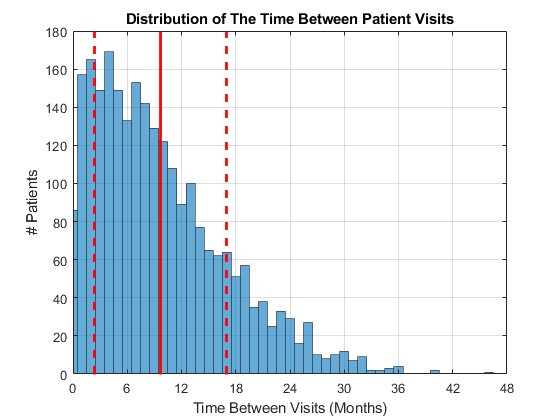

% Plot a histogram to show the distibution of times between visits
figure;
% hist(agediff(:), 0:1:50)
% % 0:1:50 represents the bin centers. `histogram` takes the bin edges as
% % its second argument. These edges are specified by -0.5:1:50.5
histogram(agediff(:), -0.5:1:50.5, 'FaceColor', '#0072BD', 'EdgeAlpha', 0.5);
grid on;
% Annotate mean & standard deviation
xline(avgagediff, 'LineWidth', 2, 'Alpha', 1, 'Color', 	'r');
xline(avgagediff + stdagediff, '--', 'LineWidth', 2, 'Alpha', 1, 'Color', 	'r');
xline(avgagediff - stdagediff, '--', 'LineWidth', 2, 'Alpha', 1, 'Color', 	'r');
% Add plot labels
xlabel('Time Between Visits (Months)')
ylabel('# Patients')
title('Distribution of The Time Between Patient Visits')
% Adjust axes
axis([0 48 0 180]);
xticks(0:6:48);

#### Figure Captions: 

A hsitogram showing the distribution of time between patient visits overlayed by lines indicating the the mean, $\mu$ (solid red), and $\mu \pm \sigma$ (mean $\pm$ standard deviation) (dashed red).

#### Conclusions:

The distribution of time between visits is positively-skewed with most patients having between 2 and 16 months between their visits.

# Does Drug Use Affect How Often a Patient Comes into the Clinic?

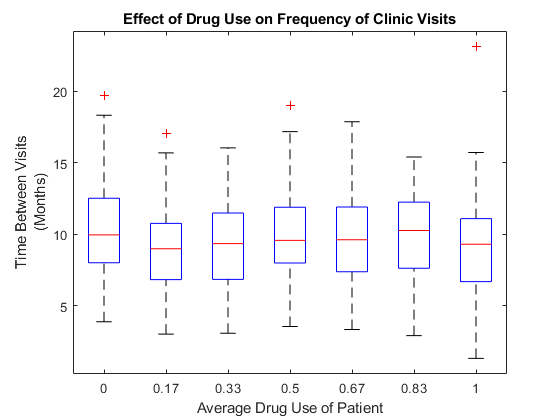

% Compute the mean drug use for each patient
avguse = mean(drug.Variables, 2);
% Compute the mean time between visits for each patient
avgvisit = mean(agediff, 2);
% Use a boxplot to answer: Does drug use affect a patient's return
% frequency?
figure;
boxplot(avgvisit, num2str(avguse), 'Positions', (0:6) ./ 6);
xtickformat('%.2g');
xlabel('Average Drug Use of Patient');
ylabel({'Time Between Visits', '(Months)'});
title('Effect of Drug Use on Frequency of Clinic Visits');

#### Figure Captions:

Boxplots showing the time between visits for patients grouped by their average drug use. The red lines indicate the group medians, the top and bottom edges of the boxes indicate the upper and lower quartiles for each group, the $+$ signs represent the outliers.

#### Conclusions:

Drug use does not have a significant impact on the time between patient visits.

# Effect of Age on TMHDS

First, we'll look at whether age is correlated with TMHDS.

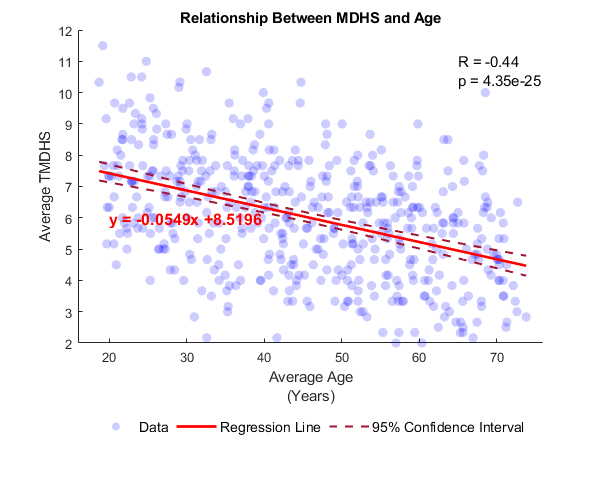

% Use a scatterplot to answer: Does the patient's age correlate with TMHDS
% mean (age, dim) of each patient
% mean (score, dim) of each patient
% scatter plot age and score
% linear regression between age and score with polyfit
% print slope and intercept
% answer the question "whether age is correlated (negatively or positively)with 
% TMHDS score" by calculating the correlation coefficient, and why? 
% corrcoef(). https://www.mathworks.com/help/matlab/ref/corrcoef.html
% plot the trend line

% Compute mean age for each patient
avgage = mean(age.Variables, 2);
% Compute mean MHDS for each patient
avgMDHS = mean(score.Variables, 2);

% Create scatter plot
figure('Position', [0 0 600 500])
scatter(avgage, avgMDHS, 50, 'filled',...
	      'MarkerFaceColor', 'blue', 'MarkerFaceAlpha', 0.2)
hold on;

% Fit data to a linear regression model
mdl = fitlm(avgage, avgMDHS);
% Compute confidence intervals and tredline
[trend, ci] = predict(mdl, sort(avgage));
% Add trendline and 95% confidence intervals to figure
plot(sort(avgage), trend, '-', 'Color', 'r', 'LineWidth', 2);
plot(sort(avgage), ci, '--', 'Color', '#A2142F', 'LineWidth', 1.5);
hold off;
% Show regression line equation in figure
text(20, 6, sprintf('y = %.4fx %+.4f', flip(mdl.Coefficients.Estimate)), ...
	   'Color', 'r', 'FontWeight', 'bold', 'FontSize', 12)

% Compute the correlation coefficient and p-value and show in figure
[R, p] = corrcoef(avgage, avgMDHS);
text(65, 11.0, sprintf('R = %.2f', R(2)), 'FontSize', 11)
text(65, 10.4, sprintf('p = %.2e', p(2)), 'FontSize', 11)

% Add plot labels
xlabel({'Average Age', '(Years)'});
ylabel('Average TMDHS');
title('Relationship Between MDHS and Age');
legend({'Data', 'Regression Line', '95% Confidence Interval'}, 'FontSize', 10.5, ...
       'Location', 'southoutside', 'Orientation', 'horizontal', 'Box', 'off');
axis([16 76 2 12]);

#### Figure Captions:

A Scatter-plot showing average TMDHS against average patient age. The scatter plot is overlayed by the regression line and its equation (solid, red), 95% confidence intervals for the regression (dashed, red), and the $R$ and $p$ values for the correlation between the variables.

#### Conclusions:

There is a statistically significant negative correlation between age and TMDHS $\left ( R = -0.44,~~p = 4.35 \times 10^{-25} \right )$ at a significance level of $\alpha = 0.05$. This implies that elderly patients have an increased likelihood of developing dementia.

# Effect of Age on The Rate of Change of TMHDS

Next, we want to ask whether TMHDS of old patients decrease faster.

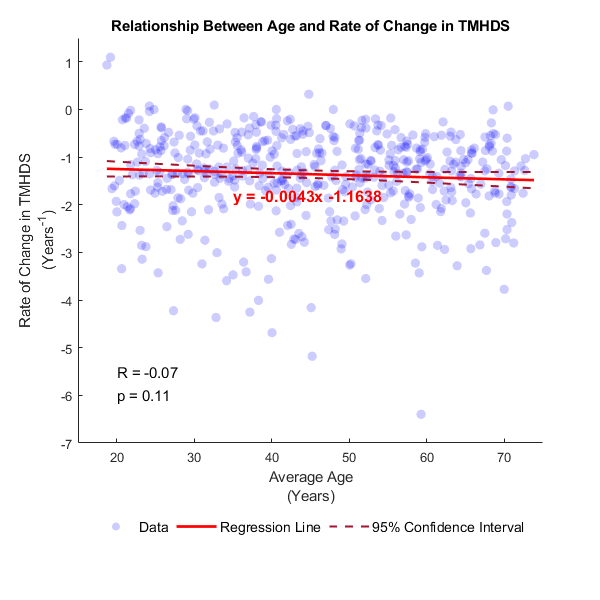

% Calculate the rate of change of TMHDS for each patient vs age.
% % Split age and score matrices by patient and pass that to polyfit
coef = splitapply(@(x,y) polyfit(x,y,1), age.Variables, score.Variables, (1:500)');
% Does this correlate with age? Plot the scatter plot and the trendline

% Compute mean age for each patient
avgage = mean(age.Variables, 2);

% Create scatter plot
figure('Position', [0 0 600 600])
scatter(avgage, coef(:, 1), 50, 'filled',...
	      'MarkerFaceColor', 'blue', 'MarkerFaceAlpha', 0.2)
hold on;

% Fit data to a linear regression model
mdl = fitlm(avgage, coef(:, 1));
% Compute confidence intervals and trendline
[trend, ci] = predict(mdl, sort(avgage));
% Add trendline and confidence intervals to figure
plot(sort(avgage), trend, '-', 'Color', 'r', 'LineWidth', 2);
plot(sort(avgage), ci, '--', 'Color', '#A2142F', 'LineWidth', 1.5);
hold off;
% Show regression line equation in figure
text(35, -1.8, sprintf('y = %.4fx %+.4f', flip(mdl.Coefficients.Estimate)), ...
	   'Color', 'r', 'FontWeight', 'bold', 'FontSize', 12)

% Compute the correlation coefficient and p-value and show in the figure
[R, p] = corrcoef(avgage, coef(:, 1));
text(20, -5.5, sprintf('R = %.2f', R(2)), 'FontSize', 11);
text(20, -6.0, sprintf('p = %.2f', p(2)), 'FontSize', 11);

% Add plot labels
xlabel({'Average Age', '(Years)'});
ylabel({'Rate of Change in TMHDS', '(Years^{-1})'});
title('Relationship Between Age and Rate of Change in TMHDS');
legend({'Data', 'Regression Line', '95% Confidence Interval'}, 'FontSize', 10.5, ...
       'Location', 'southoutside', 'Orientation', 'horizontal', 'Box', 'off');
axis([15 75 -7 1.5]);

#### Figure Captions:

A Scatter-plot showing rate of change in TMDHS against average patient age. The scatter plot is overlayed by the regression line and its equation (solid, red), 95% confidence intervals for the regression (dashed, red), and the $R$ and $p$ values for the correlation between the variables.

#### Conclusions:

There is no significant correlation between TMDHS and patient age $\left ( R = -0.07,~~p = 0.11 \right )$ at a significance level of $\alpha = 0.05$. This implies that age doesn't have an effect on how quickly dementia progressed (how quickly TMHDS decreased) in these patients. Therefore, the age of older patients does not appear to decrease faster.

# Which is More Important?

What we often want to know when there are two independent variables is: Which is more important, age or drug use? There are many ways to do this but the simplest is to group the patients. Within this set of "drug-using" patients, there are some that never tested positive for drug use. These patients can be used to determine the effect of age alone. This can then be compared to age-matched patients who tested positive for varying levels of drug use.

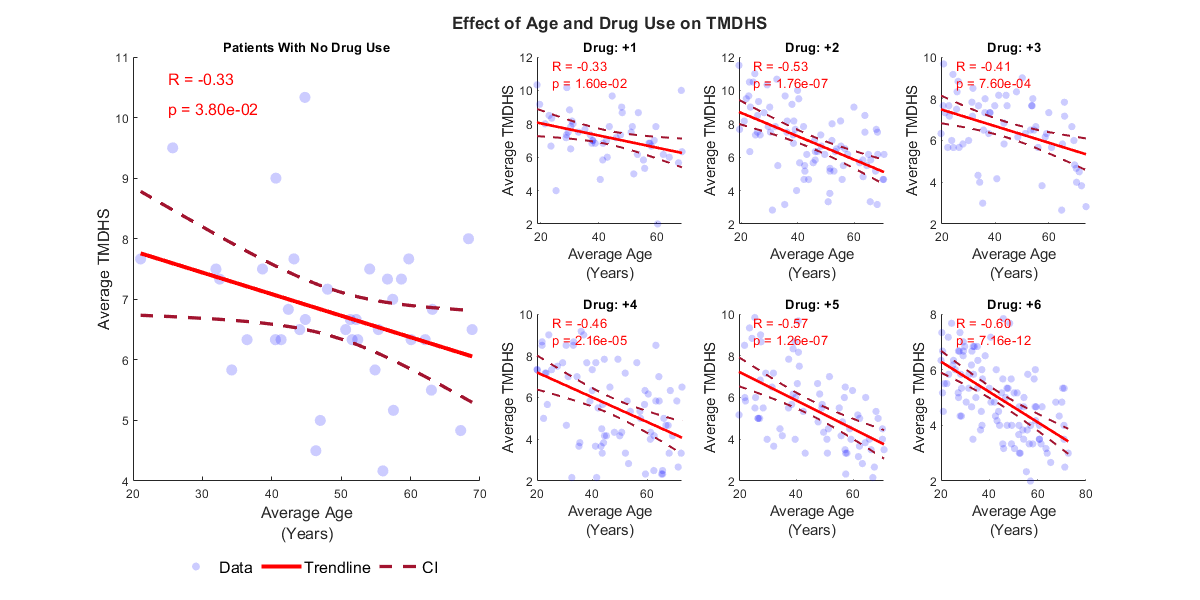

% Develop a figure that answers the question: Which has a larger effect,
% aging or drug use?

% Construct seven drug groups (0, 1, 2, 3, 4, 5, 6) based on the sum of all
% drug use for each patient. Plot linear regression of the mean age vs mean
% scores and add the trend line
% Calculate the correlation coefficient for each group
% Answer the question "which group has the highest correlation coefficient
% between age and score" and why?
figure('Position', [0 0 1200 600]);
% Create a tiled subplot layout
t = tiledlayout(2, 5);
% Specify the positions for the 6 drug-using groups
tile = [3 4 5 8 9 10];

% Loop through groups where patients exhibited drug use
for i = 1:6
	% Select the correct tile position
	nexttile(tile(i));
	% Create boolean vector for selecting patients in this group
	I = (sum(drug.Variables, 2) == i);
	% Create scatter
	scatter(avgage(I), avgMDHS(I), 30, 'filled',...
	        'MarkerFaceColor', 'blue', 'MarkerFaceAlpha', 0.2)
	hold on;
	% Fit data to a linear regression model
	mdl = fitlm(avgage(I), avgMDHS(I));
	% Compute confidence intervals and trendline
	[trend, ci] = predict(mdl, sort(avgage(I)));
	% Add trendline and confidence intervals to figure
	plot(sort(avgage(I)), trend, '-', 'Color', 'r', 'LineWidth', 2);
	plot(sort(avgage(I)), ci, '--', 'Color', '#A2142F', 'LineWidth', 1.5);
	hold off;
	% Compute the correlation coefficient and p-value and show in the figure
	[R, p] = corrcoef(avgage(I), avgMDHS(I));
	text(0.1, 0.95, sprintf('R = %.2f', R(2)), 'FontSize', 10, ...
		   'Color', 'r', 'Units', 'normalized');
	text(0.1, 0.85, sprintf('p = %.2e', p(2)), 'FontSize', 10, ...
		   'Color', 'r', 'Units', 'normalized');
	% Add plot Labels
	xlabel({'Average Age', '(Years)'}, 'FontSize', 11);
	ylabel('Average TMDHS', 'FontSize', 11);
	title(sprintf('Drug: +%i', i));
end

% Plot paients that never tested positive for drug use
nexttile(1, [2 2]);
I = (sum(drug.Variables, 2) == 0);
% Create scatter
scatter(avgage(I), avgMDHS(I), 70, 'filled',...
        'MarkerFaceColor', 'blue', 'MarkerFaceAlpha', 0.2)
hold on;
% Fit data to a linear regression model
mdl = fitlm(avgage(I), avgMDHS(I));
% Compute confidence intervals and trendline
[trend, ci] = predict(mdl, sort(avgage(I)));
% Add trendline and confidence intervals to figure
plot(sort(avgage(I)), trend, '-', 'Color', 'r', 'LineWidth', 3);
plot(sort(avgage(I)), ci, '--', 'Color', '#A2142F', 'LineWidth', 2.5);
hold off;
% Compute the correlation coefficient and p-value and show in the figure
[R, p] = corrcoef(avgage(I), avgMDHS(I));
text(0.1, 0.95, sprintf('R = %.2f', R(2)), 'FontSize', 12, ...
	   'Color', 'r', 'Units', 'normalized');
text(0.1, 0.88, sprintf('p = %.2e', p(2)), 'FontSize', 12, ...
	   'Color', 'r', 'Units', 'normalized');
% Add plot Labels
xlabel({'Average Age', '(Years)'}, 'FontSize', 12);
ylabel('Average TMDHS', 'FontSize', 12);
title('Patients With No Drug Use')

% Add legend to figure
legend({'Data', 'Trendline', 'CI'}, 'FontSize', 12, 'Location', 'southoutside', ...
	     'Units', 'normalized', 'Orientation', 'horizontal', 'box', 'off');
title(t, 'Effect of Age and Drug Use on TMDHS', 'FontWeight', 'bold', 'FontSize', 13);

#### Figure Captions:

This figure shows 7 scatter plots all plotting average TMDHS against average age for different groups. The left-most figure shows compares TMDHS and age for patients with no drug use; the 2 by 3 grid of scatterplots on the right compared TMDHS and age for patients who had different levels of drug use (ranging from one positive test up to 6). The scatter plot is overlayed by the regression line and its equation (solid, red), 95% confidence intervals for the regression (dashed, red), and the $R$ and $p$ values for the correlation between the variables.

#### Conclusions:

In all cases, there is a significant correlation between TMDHS and age. The correlation is highest for patients who tested posititive for drug use at all 6 visits $\left ( R = -0.60,~~p = 7.16 \times 10^{-12}\right )$, followed by those who tested positive 5 times, 4 times, and so on. This suggests that that as patient drug use increases, patients become more likely to develop dementia as they age (their TMDHS tends to get lower as age increases).

# Bonus Question (5 Points)

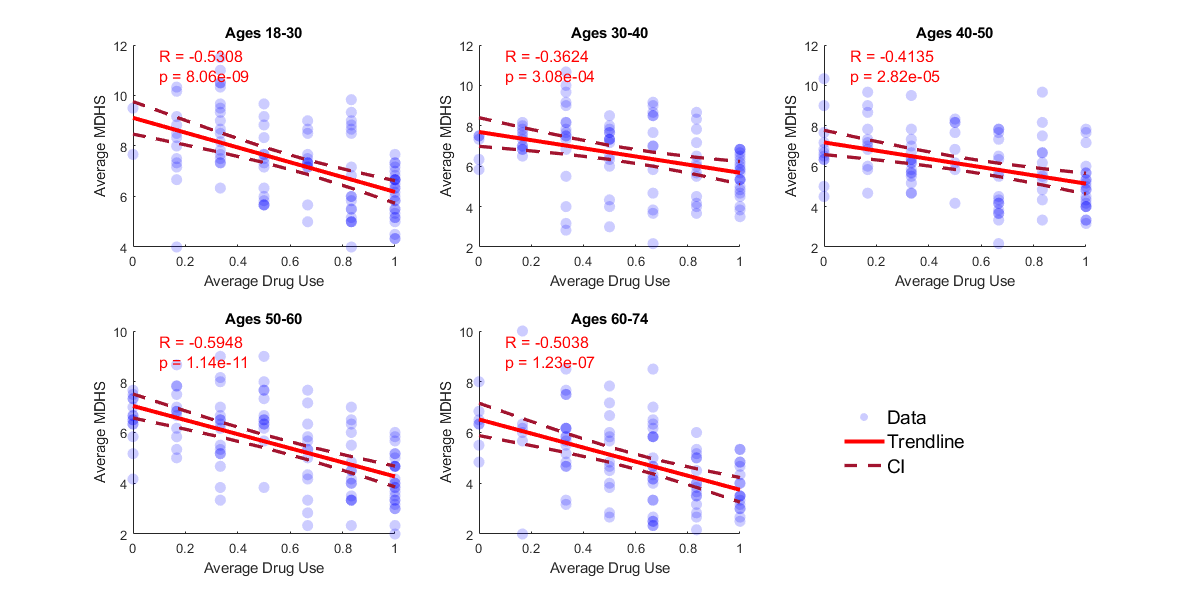

% In 5 groups of mean age between 
% [18,30], (30,40], (40,50], (50,60], (60-74]
% Plot linear regression of the mean drug use vs. mean scores
% Calculate correlation coefficient for each group
% Answer the question "Which age group has the highest correlation between
% drug use and score" and why?

% Create age groups
agegrp = zeros(size(avgage));
agegrp(avgage <= 30) = 1;
agegrp((avgage > 30) & (avgage <= 40)) = 2;
agegrp((avgage > 40) & (avgage <= 50)) = 3;
agegrp((avgage > 50) & (avgage <= 60)) = 4;
agegrp(avgage > 60) = 5;

figure('Position', [0 0 1200 600]);
% Create subplot layout for plots
t = tiledlayout('flow');
% In this case, splitapply takes avguse, avgMDHS, and agegrp, splits them
% based on groups specified in agegrp and passes the subgroups as agruments
% to my plotting function `bonusPlot`
splitapply(@bonusPlot, avguse, avgMDHS, agegrp, agegrp);
% Add a figure legend
legend({'Data', 'Trendline', 'CI'}, 'FontSize', 14, 'Location', [0.7 0.2 1 1], ...
	      'Units', 'normalized', 'box', 'off');

#### Figure Captions:

This figure shows 5 scatter plots all plotting average TMDHS against average drug use for different age groups. The scatter plot is overlayed by the regression line and its equation (solid, red), 95% confidence intervals for the regression (dashed, red), and the $R$ and $p$ values for the correlation between the variables.

#### Conclusions:

Patients between 50 and 60 years old exhibite the highest correlation between drug use and TMDHS $\left ( R = -0.5948, p = 1.14 \times 10^{-11} \right )$.

## Local Functions

function bonusPlot(x, y, g)
% This function generates scatterplots with fitted tredlines and confidence
% intervals for grouped data from `splitapply`
  % Create a cell array with entries corresponding to each group
  grps = {'18-30', '30-40', '40-50', '50-60', '60-74'};
	% Determine the current group by extracting a unique element from the grouping
	% vector g
  g = unique(g);
	% Select the next available subplot
  nexttile;
	% Create the scatter plot
	scatter(x, y, 70, 'filled', 'MarkerFaceColor', 'blue', 'MarkerFaceAlpha', 0.2);
	hold on;
	% Fit the data to a linear regression model
	mdl = fitlm(x, y);
	% Compute the tredline and 95% confidence intervals & show them in the figure
	[trend, ci] = predict(mdl, sort(x));
	plot(sort(x), trend, '-', 'Color', 'r', 'LineWidth', 3);
	plot(sort(x), ci, '--', 'Color', '#A2142F', 'LineWidth', 2.5);
	hold off;
	% Compute the correlation coefficient and pvalue & show them in the figure
	[R, p] = corrcoef(x,y);
	text(0.1, 0.95, sprintf('R = %.4f', R(2)), 'FontSize', 12, ...
	   'Color', 'r', 'Units', 'normalized');
	text(0.1, 0.85, sprintf('p = %.2e', p(2)), 'FontSize', 12, ...
	   'Color', 'r', 'Units', 'normalized');
	% Add plot labels
	title(['Ages ' grps{g}])
	xlabel('Average Drug Use');
	ylabel('Average MDHS');
end